# Test Case - Motor Generator 1

mdl = "MotorGenerator1_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
MotorGenerator1_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Eng Trq Cmd", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Eng Trq Cmd", Time="2");
simIn = setBlockParameter(simIn, mdl+"/Eng Trq Cmd", After="0");

simIn = setBlockParameter(simIn, mdl+"/MG1 Trq Cmd", Before="0");
simIn = setBlockParameter(simIn, mdl+"/MG1 Trq Cmd", Time="1");
simIn = setBlockParameter(simIn, mdl+"/MG1 Trq Cmd", After="0");

% Initial conditions

simIn = setVariable(simIn, "initial.engine_speed_rpm", 0);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "1000");

% Run simulation
simOut = sim(simIn);

% Copy simlog to the base workspace
% so that sscexplore can load it.
simlog = simOut.simlog;

## Visualize Simulation Result

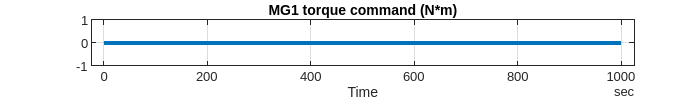

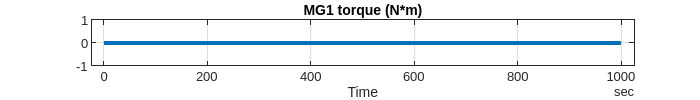

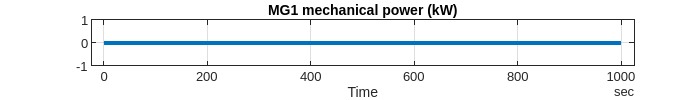

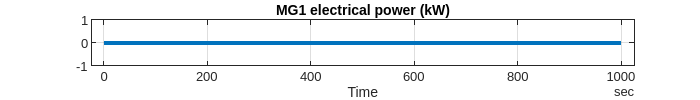

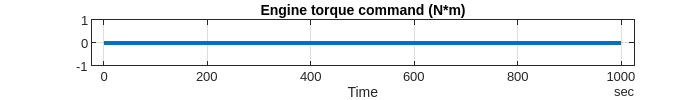

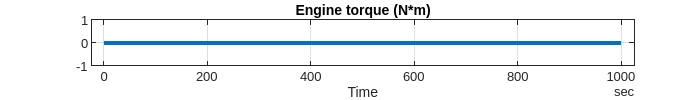

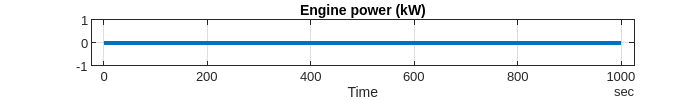

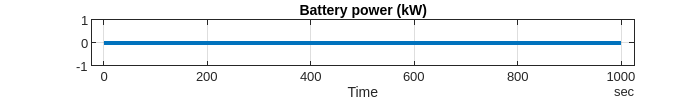

simData = extractTimetable(simOut.logsout);

MotorGenerator1_Component_plotResults(SimData = simData, FigureHeight = 100);

*Copyright 2021-2022 The Mathworks, Inc.*